% Function for title name
function title_name(filename, index)
    [~, name, ~] = fileparts(filename);
    word = ' resultant';
    if index == 0
        title(name);
    else
        title_text = [name, '', word];
        title(title_text);
    end
end

% Open a dialogue box for selecting the .MAT file
[filename, filepath] = uigetfile('*.mat', 'Select a MAT File');
if isequal(filename,0)
    disp('The dialogue box is closed');
    return;
end

fullpath = fullfile(filepath, filename);

% Load .MAT file
data = load(fullpath);

% Extract variables from the .MAT file
nodes = data.coord;
bearings = data.bearing;
external_forces = data.F;
connectivity_matrix = data.conn;

% Display the extractded variables
disp('Nodes:'); disp(nodes); 

Nodes:
     0     0
     2     2
     2     0
     4     2
     4     0
     6     2
     6     0
     8     0



disp('Bearings:'); disp(bearings);

Bearings:
     1     1
     1     2
     8     2



disp('External Forces:'); disp(external_forces);

External Forces:
     6     0    -1
     5     0    -1
     7     0    -1



disp('Connectivity Matrix:'); disp(connectivity_matrix);

Connectivity Matrix:
     1     2
     2     4
     1     4
     1     3
     3     4
     3     5
     5     4
     4     6
     4     8
     4     7
     6     8
     7     8
     5     7



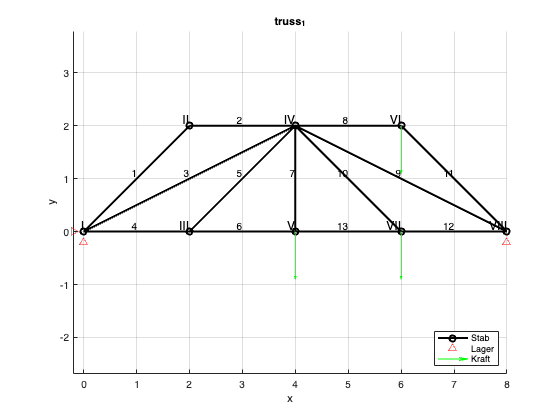


figure;
axis equal;
hold on;
grid on;
xlabel('x')
ylabel('y')
title_name(filename, 0);

% Mark the nodes
for i = 1:size(nodes, 1)
     text(nodes(i,1), nodes(i,2), Num2roman(i), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 12);
end

% Plot nodes and bars
for i = 1:size(connectivity_matrix, 1)
    x = [nodes(connectivity_matrix(i,1), 1), nodes(connectivity_matrix(i,2), 1)];
    y = [nodes(connectivity_matrix(i,1), 2), nodes(connectivity_matrix(i,2), 2)];
    plot_stab = plot(x, y, '-o', 'Color', 'k', 'LineWidth', 2, 'MarkerEdgeColor', 'k', 'MarkerSize', 6);
    text(mean(x), mean(y), num2str(i), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10);
end

% Plot bearings
for i = 1:1:size(bearings, 1)
    x = nodes(bearings(i,1), 1);
    y = nodes(bearings(i,1), 2);
    plot_lager1 = plot(x, y - 0.2, '^', 'Color', 'r', 'MarkerSize', 7, 'DisplayName', 'Bearings');
    if(bearings(i,2) == 1)
        plot_lager1 = plot(x - 0.2, y, '>', 'Color', 'r', 'MarkerSize', 7, 'DisplayName', 'Bearings');    
    end    
end 

% Plot forces
for i = 1:1:size(external_forces, 1)
    x = nodes(external_forces(i,1), 1);
    y = nodes(external_forces(i,1), 2);
    plot_kraft = quiver(x, y, external_forces(i,2), external_forces(i,3), 'Color','green');    
end  

% Label axes and add legend
legend([plot_stab, plot_lager1, plot_kraft], 'Stab', 'Lager', 'Kraft', 'Location', 'southeast');


% Calculate degree of freedom
degree_of_freedom = 2 * size(nodes,1) - (size(bearings,1) + size(connectivity_matrix,1));
external_degree_of_freedom = 3 - size(bearings,1);

% Load bearing capacity
if(degree_of_freedom <= 0 && external_degree_of_freedom <= 0)
    disp('Rigid and Capable for load-bearing')
end

Rigid and Capable for load-bearing



disp('Degree of freedom of the bounded system'); disp(degree_of_freedom);

Degree of freedom of the bounded system
     0




% Static determinateness
if(degree_of_freedom == 0)
    disp('Static Determinateness fulfilled');

% Statically undetermines
else
    error ('Invalid degree of freedom and Static Determinateness not fulfilled. The script is terminated');
end

Static Determinateness fulfilled



% Calculation of angle alpha
% alpha = arctangent[(y2 - y1) / (x2 - x1)] 
% This has to be checked with the condition if y1 > y2 or y1 < y2
alpha = zeros([size(connectivity_matrix,1), 1]);
alphar = zeros([size(connectivity_matrix,1), 1]);

for i = 1:1:size(connectivity_matrix,1)
    if(nodes(connectivity_matrix(i,2),2) <  nodes(connectivity_matrix(i,1),2))
        alpha (i,1) = pi/2 + atan((nodes(connectivity_matrix(i,1),2)-nodes(connectivity_matrix(i,2),2) )/(nodes(connectivity_matrix(i,2),1)-nodes(connectivity_matrix(i,1),1)));
    else
        alpha (i,1) = atan((nodes(connectivity_matrix(i,2),2)-nodes(connectivity_matrix(i,1),2) )/(nodes(connectivity_matrix(i,2),1)-nodes(connectivity_matrix(i,1),1)));
    end
end

disp(alpha);

    0.7854
         0
    0.4636
         0
    0.7854
         0
    1.5708
         0
    2.0344
    2.3562
    2.3562
         0
         0




% Angle alpha-r
for i = 1:1:size(connectivity_matrix,1)
    alphar (i,1) = atan((nodes(connectivity_matrix(i,2), 2)-nodes(connectivity_matrix(i,1), 2) )/(nodes(connectivity_matrix(i,2), 1)-nodes(connectivity_matrix(i,1), 1)));
end

disp(alphar);

    0.7854
         0
    0.4636
         0
    0.7854
         0
    1.5708
         0
   -0.4636
   -0.7854
   -0.7854
         0
         0




% Formulating matrix form
% A . r + f = 0  --> Formulate for 'A' and 'f' to find 'r'

% Create zero matrices A and r
A = zeros([2 * size(nodes,1), ((size(connectivity_matrix,1) + size(bearings,1)))]);
f = zeros([2 * size(nodes,1), 1]);

% Compute for 'f'
for i = 1:1:size(external_forces,1)
    f(external_forces(i,1) * 2 - 1, 1) = external_forces(i, 2);
    f(external_forces(i,1) * 2, 1) = external_forces(i, 3);    
end

% Compute for 'A'
for i = 1:1:size(bearings,1)
    if(bearings(i,2) == 1)
        A(bearings(i,1) * 2 - 1, i) = 1;
    else
        A(bearings(i,1) * 2, i) = 1;
    end
end

for i = 1:1:size(connectivity_matrix,1)
    if(nodes(connectivity_matrix(i,2), 1) > nodes(connectivity_matrix(i,1), 1))
        A(connectivity_matrix(i,1) * 2 - 1, i + size(bearings,1)) = cos(abs(alphar(i,1)));
        A(connectivity_matrix(i,2) * 2 - 1, i + size(bearings,1)) = -cos(abs(alphar(i,1)));
    else
        A(connectivity_matrix(i,1) * 2 - 1, i + size(bearings,1)) = -cos(abs(alphar(i,1)));
        A(connectivity_matrix(i,2) * 2 - 1, i + size(bearings,1)) = cos(abs(alphar(i,1)));    
    end
    if(nodes(connectivity_matrix(i,2), 2) > nodes(connectivity_matrix(i,1), 2))    
        A(connectivity_matrix(i,1) * 2, i + size(bearings,1)) = sin(abs(alphar(i,1)));
        A(connectivity_matrix(i,2) * 2, i + size(bearings,1)) = -sin(abs(alphar(i,1)));
    else
        A(connectivity_matrix(i,1) * 2, i + size(bearings,1)) = -sin(abs(alphar(i,1)));
        A(connectivity_matrix(i,2) * 2, i + size(bearings,1)) = sin(abs(alphar(i,1)));
    end
end

disp(A);

    1.0000         0         0    0.7071         0    0.8944    1.0000         0         0         0         0         0         0         0         0         0
         0    1.0000         0    0.7071         0    0.4472         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.7071    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.7071         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   -1.0000    0.7071    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    0.7071         0         0         0         0         0         0         0         0
         0         0         0    

disp(f);

     0
     0
     0
     0
     0
     0
     0
     0
     0
    -1
     0
    -1
     0
    -1
     0
     0




% Calculare r
% r = - [(A ^ -1) . f]
r = linsolve(A, -f);
disp(r);

         0
    1.0000
    2.0000
   -0.0000
   -0.0000
   -2.2361
    2.0000
         0
    2.0000
    1.0000
   -1.0000
   -2.2361
    1.4142
   -1.4142
    3.0000
    2.0000



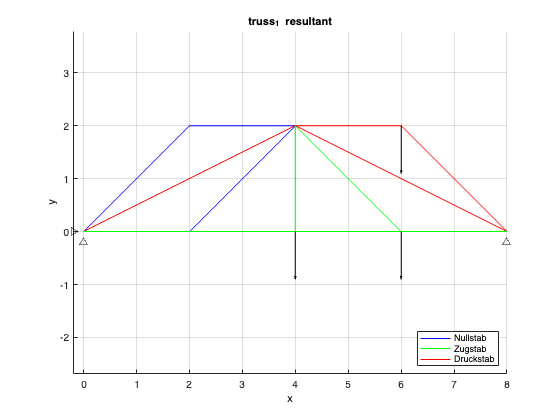


% Visualise the truss according to the load condition
figure;
axis equal;
hold on;
grid on;
xlabel('x')
ylabel('y')
title_name(filename, 1)

% Plot of 0 length to skip the inexistence of any load condition
plot_nullstab = plot([0 0],[0 0], 'blue');
plot_zugstab = plot([0 0],[0 0], 'green');
plot_druckstab = plot([0 0],[0 0], 'red');

% Ploting each beam corresponding to the load condition
for i = 1:1:size(connectivity_matrix,1)
    x1 = nodes(connectivity_matrix(i,1), 1); 
    x2 = nodes(connectivity_matrix(i,2), 1);
    y1 = nodes(connectivity_matrix(i,1), 2);
    y2 = nodes(connectivity_matrix(i,2), 2); 
    if((r(i+3,1) < 0.05) && (r(i+3,1) > -0.05))
        plot_nullstab = plot([x1 x2], [y1 y2],'blue');
        hold on
    end
    if(r(i+3,1) > 0.05)
        plot_zugstab = plot([x1 x2], [y1 y2],'green');
        hold on
    end
    if(r(i+3,1) < -0.05)
        plot_druckstab = plot([x1 x2], [y1 y2],'red');
        hold on
    end
end

% Plot bearings
for i = 1:1:size(bearings, 1)
    x = nodes(bearings(i,1), 1);
    y = nodes(bearings(i,1), 2);
    plot_lager1 = plot(x, y - 0.2, '^', 'Color', 'k', 'MarkerSize', 7, 'DisplayName', 'Bearings');
    if(bearings(i,2) == 1)
        plot_lager1 = plot(x - 0.2, y, '>', 'Color', 'k', 'MarkerSize', 7, 'DisplayName', 'Bearings');    
    end    
end 

% Plot forces
for i = 1:1:size(external_forces, 1)
    x = nodes(external_forces(i,1), 1);
    y = nodes(external_forces(i,1), 2);
    plot_kraft = quiver(x, y, external_forces(i,2), external_forces(i,3), 'Color','k');    
end
legend([plot_nullstab, plot_zugstab, plot_druckstab], 'Nullstab', 'Zugstab', 'Druckstab', 'Location', 'southeast');


% Save results to a new .MAT file
save('result_truss.mat', "nodes", "bearings", "external_forces", "connectivity_matrix", "A", "f", "r", "alphar", "alpha", "degree_of_freedom", "external_degree_of_freedom");


ans =      3     2
